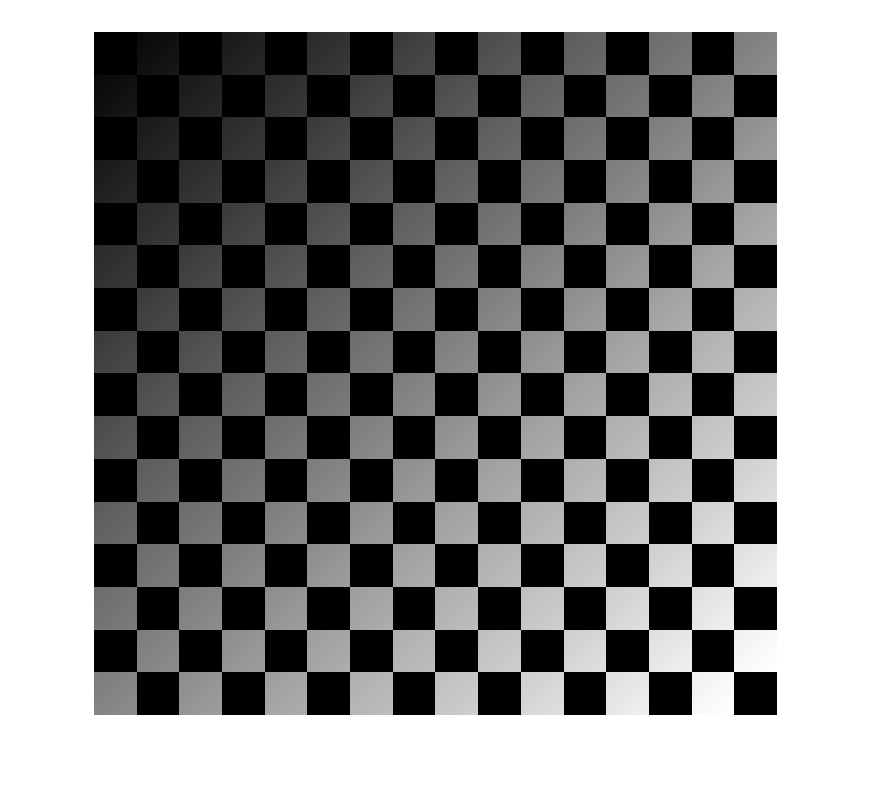

cb_shaded=im2double(imread("checkerboard1024-shaded.tif"));
cb_shaded=rescale(cb_shaded,0,1);
imshow(cb_shaded,[])

Add noise to the checkerboard 

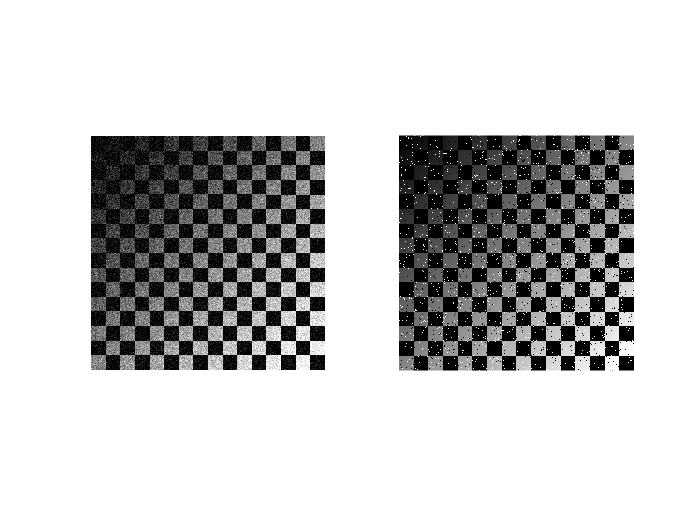

Imgn =imnoise(cb_shaded,"gaussian");
ImgnSp =imnoise(cb_shaded,"salt & pepper");
figure
subplot(1,2,1)
imshow(Imgn)
subplot(1,2,2)
imshow(ImgnSp)

Applying both filter to compare the results

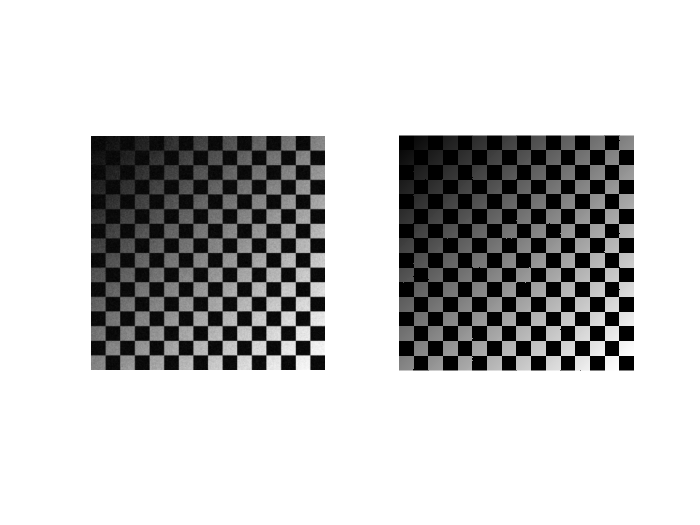

guIM=imgaussfilt(Imgn,2);
IMsp =medfilt2(ImgnSp);
figure
subplot(1,2,1)
imshow(guIM)
subplot(1,2,2)
imshow(IMsp)

  dividing the original image by the result, Use the "elementwise" division, which in MATLAB is the ./ command

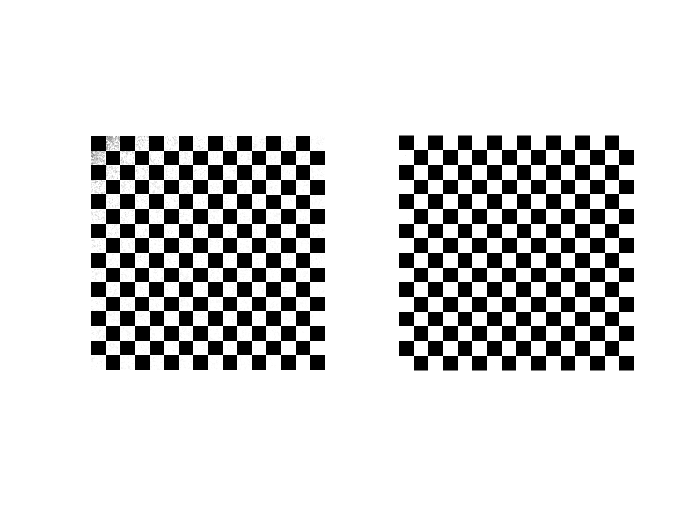

DIV=cb_shaded ./ guIM;
DIV1=cb_shaded ./ IMsp;
figure
subplot(1,2,1)
imshow(DIV)
subplot(1,2,2)
imshow(DIV1)